## Dual-Satellite Lunar Navigaiton System

*Copyright :  Toshiki Tanaka, University of Houston, 2020*

*Any questions and error report -> ttanaka@uh.edu*

### Initialization

clear
clc

#### Select Navigation Method

navigationMethod = 4; % 4: DMSTR(synchronized), 5: DMSTR(unsynchronized)

#### Set Landing Site Information

% Landing site
landingLatitude = -90; 
landingLongitude = 90;

% read lunar DEM data of the selected landing site
realDEMdata = load('sample_lunarDEM_5m-grid_5000x5000.mat');
realDEM = realDEMdata.aaa;

#### Static Paramters

epoch = 0.5; %[min]
missionDuration =15000/epoch;

% lunar general parameter
lunarRadius = 1737000; % 1737[km]
lunarRotationPeriod = 27.32*24*60/epoch;

% Navigation parameter
observationTime = 2; % the length of observation epochs, i.e., td in the below figure
travelingTime = 1; % the rover moves for one epoch after the observation epochs
updateTime = 10; % Newton Raphson Calculation parameter

if navigationMethod == 4
    time_diff = 0;
elseif navigationMethod == 5
    time_diff = 1;
end

% Rover trajectory creation parameter
roverInitialOrientation = pi/2; % rad : 90deg X-direction, 0deg Y-direction
roverTravelingSpeed = 7.5*epoch; % distance/min
roverOrientationControl = pi/3;

% Satellite trajectory creation parameter
rotationFlag_s1 = 1; % 0 if the trajectory file to read is made in a rotational frame
rotationFlag_s2 = 1; % 0 if the trajectory file to read is made in a rotational frame
orbitDeterminationPeriod = 1440/epoch;

% System Error parameters
clockErrorEnable = 1;
observationNoiseEnable = 1;
satODErrorEnable = 1;
timeTagErrorEnable = 1;
demErrorEnable = 1;
processErrorEnable = 1;
digitalizationFlag = 1;
realDEMFlag = 1; % 0: spherical moon model, 1: real lunar DEM 

% Clock error
if clockErrorEnable == 1
    % white noise, Bias, random walk
    % Clock errors are effectively removed by two-way ranging in advance
    clockErrorParam_R = [0, 0, 0];
    clockErrorParam_L = [0, 0, 0];
    clockErrorParam_S1 = [0, 0, 0];
    clockErrorParam_S2 = [0, 0, 0];
else
    clockErrorParam_R = [0, 0, 0];
    clockErrorParam_L = [0, 0, 0];
    clockErrorParam_S1 = [0, 0, 0];
    clockErrorParam_S2 = [0, 0, 0];
end

% Observation white noise
if observationNoiseEnable == 1
    % range white noise, bias, doppler white noise, bias
    observationNoiseParam = [0.2, 0, 0, 0]; % [m, Hz]
%     observationNoiseParam = [2.0, 0, 0, 0]; % [m, Hz]
else
    observationNoiseParam = [0, 0, 0, 0];
end

% Orbit Determination Error
if satODErrorEnable == 1
    % white noise (Rad, Along, Cross), Systematic (Rad, Along, Cross)
%     orbitDeterminationErrorParam_S= [10.0, 100.0, 100.0, 20.0, 200.0, 200.0]; % [m]
%     orbitDeterminationErrorParam_S= [10.0, 100.0, 100.0, 2.0, 20.0, 20.0]; % [m]
    orbitDeterminationErrorParam_S= [1.0, 10.0, 10.0, 2.0, 20.0, 20.0]; % [m]
else
    orbitDeterminationErrorParam_S= [0, 0, 0, 0, 0, 0];
end

% DEM Error
if demErrorEnable == 1
    % white noise, Systematic
    demErrorParam = [10.0, 5.0]; % [m]
else
    demErrorParam = [0, 0];
end

% Receiver Time Tag Error
if timeTagErrorEnable == 1
    % Bias, random walk
    timeTagErrorParam_S = [100.0, 1e-8]; % [ms, ms/min]
else
    timeTagErrorParam_S = [0, 0];
end

% Processing time delay error (only for two-way ranging)
if processErrorEnable == 1
    % white noise, Systematic, Bias
    processErrorParam_R = [20e-9, 20e-9, 0]; % [ns]
    processErrorParam_L = [20e-9, 20e-9, 0]; 
%     processErrorParam_R = [200e-9, 200e-9, 0]; % [ns]
%     processErrorParam_L = [200e-9, 200e-9, 0]; 
else
    processErrorParam_R = [0, 0];
    processErrorParam_L = [0, 0];
end

% Sensor Parameter
frequency = 1500000000; % 1.5GHz
rangeResolution = 0.4; % [m]
dopplerResolution = 0.2; % [Hz]

% Report generation
reportGenerationFlag = 1;


### Main Function

This code virtually creates two satellites:

- One is the satellite position of the present epoch, and the other one is the satellite position of the future epoch (= present epoch + td).

- The rover will stay in the same position until the satellite position of the present epoch arrives at the satellite position of the future epoch at the observed timing.

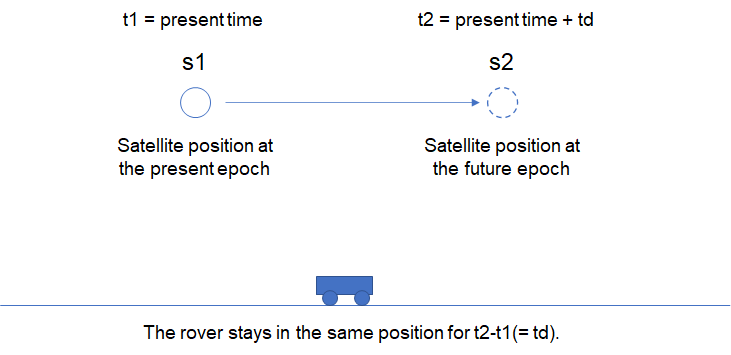

% Read a satellite trajectory file
realorbit = load('sample_LLO_300km_inc110_phase0.mat');
satPositionVectorRaw = realorbit.satPositionVectorDebug;
% FDMA: two-way rangings of the rover and lander occur at the same time (time_diff = 0)
% TDMA: two-way rangings of the rover and lander occur at different timing
satPositionIntertia_s1r = satTrajectoryCreation(satPositionVectorRaw, rotationFlag_s1, lunarRotationPeriod, missionDuration);
satPositionIntertia_s2r = satTrajectoryCreationWithOffset(satPositionVectorRaw, rotationFlag_s2, lunarRotationPeriod, missionDuration, observationTime);
satPositionIntertia_s1l = satTrajectoryCreationWithOffset(satPositionVectorRaw, rotationFlag_s1, lunarRotationPeriod, missionDuration, time_diff);
satPositionIntertia_s2l = satTrajectoryCreationWithOffset(satPositionVectorRaw, rotationFlag_s2, lunarRotationPeriod, missionDuration, observationTime+time_diff);
        
% Convert satellite trajectory data from a moon-centered rotation frame to a topocentric frame
satPositionTopocentric_s1r = FrameConversion_i2t(satPositionIntertia_s1r, landingLatitude, landingLongitude, missionDuration);
satPositionTopocentric_s2r = FrameConversion_i2t(satPositionIntertia_s2r, landingLatitude, landingLongitude, missionDuration);
satPositionTopocentric_s1l = FrameConversion_i2t(satPositionIntertia_s1l, landingLatitude, landingLongitude, missionDuration);
satPositionTopocentric_s2l = FrameConversion_i2t(satPositionIntertia_s2l, landingLatitude, landingLongitude, missionDuration);

% Create a rover and lander trajectory file
[roverPositionTopocentric, roverOrientationHistory, roverTravelingSpeedHistory, motionFlag, totalDistance, availability] = roverTrajectoryCreation(roverInitialOrientation, roverTravelingSpeed, roverOrientationControl, observationTime, travelingTime, satPositionTopocentric_s1r, satPositionTopocentric_s2r, missionDuration);
landerPositionTopocentric = landerTrajectoryCreation(missionDuration);

% Identify rover's and lander's lattitude using Lunar DEM data
roverPositionTopocentric = altitudeAcquisitionFromDEM(roverPositionTopocentric, realDEM, realDEMFlag, missionDuration);
landerPositionTopocentric = altitudeAcquisitionFromDEM(landerPositionTopocentric, realDEM, realDEMFlag, missionDuration);

% adding DEM error
roverPositionTopocentric = demErrorAddition(roverPositionTopocentric, demErrorParam, demErrorEnable, missionDuration);

% Pseudorange calculation
zeroDelay = zeros(1,missionDuration);
rangeS1R_true = rangeCalculation_Matrix_DMSTR(satPositionTopocentric_s1r, roverPositionTopocentric, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zeroDelay, zeroDelay, missionDuration);
rangeS2R_true = rangeCalculation_Matrix_DMSTR(satPositionTopocentric_s2r, roverPositionTopocentric, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zeroDelay, zeroDelay, missionDuration);
rangeS1L_true = rangeCalculation_Matrix_DMSTR(satPositionTopocentric_s1l, landerPositionTopocentric, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zeroDelay, zeroDelay, missionDuration);
rangeS2L_true = rangeCalculation_Matrix_DMSTR(satPositionTopocentric_s2l, landerPositionTopocentric, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zeroDelay, zeroDelay, missionDuration);
  
% adding clock error, observation error, and process delay time error to range
[rangeS1R_ob, rangeS2R_ob, rangeS1L_ob, rangeS2L_ob] = rangeErrorAddition_DMSTR(satPositionTopocentric_s1r, satPositionTopocentric_s2r, satPositionTopocentric_s1l, satPositionTopocentric_s2l, roverPositionTopocentric, landerPositionTopocentric, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, clockErrorParam_R, clockErrorParam_L, clockErrorParam_S1, clockErrorParam_S2, orbitDeterminationPeriod, observationNoiseParam, processErrorParam_R, processErrorParam_L, clockErrorEnable, observationNoiseEnable, processErrorEnable, missionDuration, observationTime);

% taking into account the range sensor's resolution
[rangeS1R_ob, rangeS2R_ob, rangeS1L_ob, rangeS2L_ob] = rangeDigitalization(rangeS1R_ob, rangeS2R_ob, rangeS1L_ob, rangeS2L_ob, rangeResolution, digitalizationFlag, missionDuration);
      
% adding the same satellite orbit determination error to four observations
[satPositionIntertia_s1r_ob, satPositionIntertia_s2r_ob, satPositionIntertia_s1l_ob, satPositionIntertia_s2l_ob] = satelliteODErrorAddition_DMSTR(satPositionIntertia_s1r, satPositionIntertia_s2r, satPositionIntertia_s1l, satPositionIntertia_s2l, orbitDeterminationErrorParam_S, satODErrorEnable, missionDuration, observationTime, time_diff);

% adding the same time tag error  to four observations
[satPositionIntertia_s1r_ob, satPositionIntertia_s2r_ob, satPositionIntertia_s1l_ob, satPositionIntertia_s2l_ob] = satelliteTimeTagErrorAddition_Twoaway(satPositionIntertia_s1r_ob, satPositionIntertia_s2r_ob, satPositionIntertia_s1l_ob, satPositionIntertia_s2l_ob, timeTagErrorParam_S, timeTagErrorEnable, epoch, missionDuration, observationTime, time_diff);

% frame conversion
satPositionTopocentric_s1r_ob = FrameConversion_i2t(satPositionIntertia_s1r_ob, landingLatitude, landingLongitude, missionDuration);
satPositionTopocentric_s2r_ob = FrameConversion_i2t(satPositionIntertia_s2r_ob, landingLatitude, landingLongitude, missionDuration);
satPositionTopocentric_s1l_ob = FrameConversion_i2t(satPositionIntertia_s1l_ob, landingLatitude, landingLongitude, missionDuration);
satPositionTopocentric_s2l_ob = FrameConversion_i2t(satPositionIntertia_s2l_ob, landingLatitude, landingLongitude, missionDuration);

% Rover's position estimation by Single-differenced Two-way
[roverPositionTopocentric_est, DOP] = SD_DMSTR(satPositionTopocentric_s1r_ob, satPositionTopocentric_s2r_ob, satPositionTopocentric_s1l_ob, satPositionTopocentric_s2l_ob, landerPositionTopocentric, rangeS1R_ob, rangeS2R_ob, rangeS1L_ob, rangeS2L_ob, 1, updateTime, motionFlag, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, realDEMFlag, realDEM, missionDuration);


### Log

*Generate summary log*

% log
time = 1:missionDuration;
roverPositionError = zeros(3,missionDuration);

for t=time
    if motionFlag(t) == 2
        if t+observationTime+travelingTime < missionDuration
            roverPositionError(:,t+1+travelingTime) = roverPositionTopocentric(:,t+1+travelingTime)-roverPositionTopocentric_est(:,t+1+travelingTime);
       end
    end
end

twodrms_x = 2*nanrms(abs(roverPositionError(1,:)));
twodrms_y = 2*nanrms(abs(roverPositionError(2,:)));
twodrms_z = 2*nanrms(abs(roverPositionError(3,:)));
totalGDOP = nanrms(DOP(1,:));
totalXDOP = nanrms(DOP(2,:));
totalYDOP = nanrms(DOP(3,:));
twodrms_total = sqrt(twodrms_x^2+twodrms_y^2);
        
log(1)=totalDistance;
log(2)=twodrms_total;
log(3)=twodrms_x;
log(4)=twodrms_y;
log(5)=totalGDOP;
log(6)=totalXDOP;
log(7)=totalYDOP;
log(8)=availability;    
    

### Result Report Generator

*Generate report*

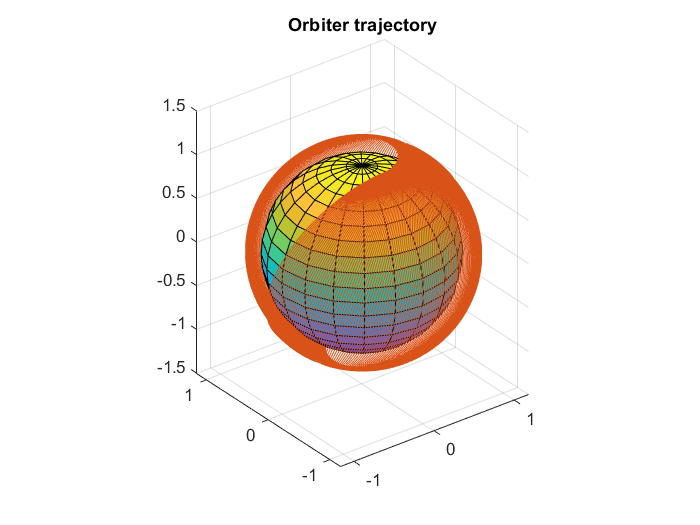

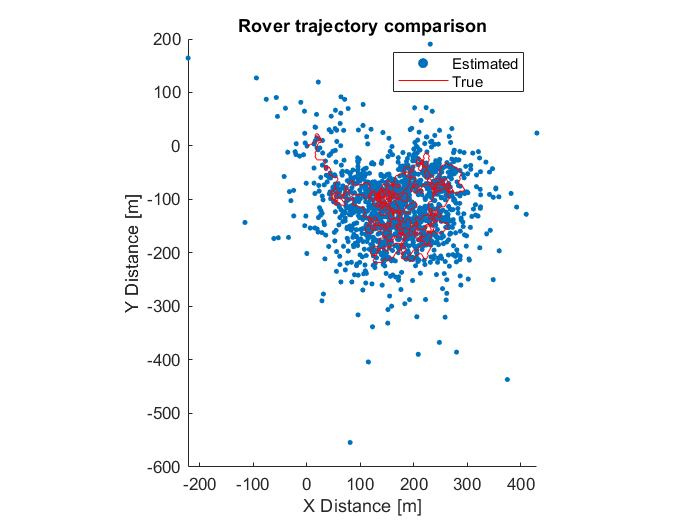

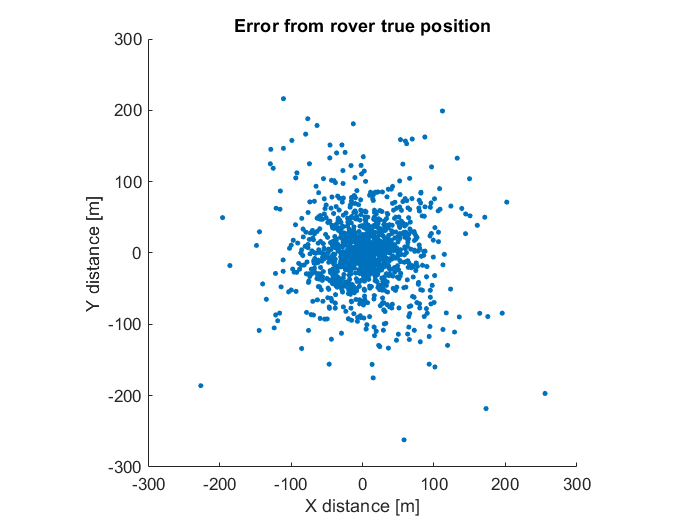

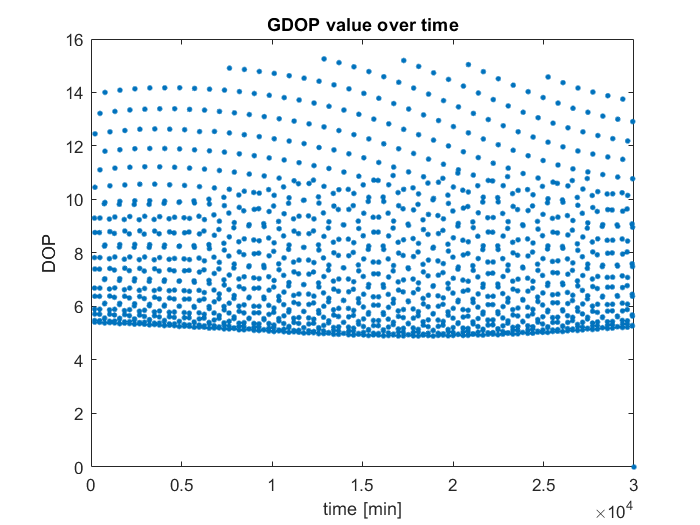

Error using mlreportgen.report.internal.Document/close
"Cannot remove directory: C:/Users/bumpb/Dropbox/Project/UT/Research/matlab Lunar navigation simulation/LNavigation Mode 4 lat -90 lon 90 ob 2_FO

Error in mlreportgen.report.ReportBase/close

if reportGenerationFlag == 1
    
    import mlreportgen.report.* 
    import mlreportgen.dom.* 
    
    str = sprintf('LNavigation Mode %d lat %d lon %d ob %d', navigationMethod, landingLatitude, landingLongitude, observationTime);
    rpt = Report(str,'pdf'); 
    
    tp = TitlePage; 
    tp.Title = 'Lunar Navigation Analysis'; 
    tp.Author = 'Toshiki Tanaka'; 
    
    add(rpt,tp);  
    
    ch0 = Chapter; 
    ch0.Title = 'Introduction'; 
    paraCh0 = Paragraph('This document summarizes lunar navigation simulation resultes with different parameters.');
    add(ch0,paraCh0);
    add(rpt,ch0); 
    
    ch1 = Chapter; 
    ch1.Title = 'Input Parameters and Results Summary'; 
    paraCh1_1 = Paragraph('This chapter summarized the parameters used in the simulation.');
    paraCh1_2 = Paragraph(' ');
    add(ch1,paraCh1_1);
    add(ch1,paraCh1_2);
    
    table1 = FormalTable({
    'epoch' epoch 'min';
    'mission Duration' missionDuration 'epoch';
    'observation Time' observationTime 'epoch';
    'traveling Time', travelingTime,'epoch';
    'landing Latitude', landingLatitude,'deg';
    'landing Longitude', landingLongitude,'deg';
    'navigationMethod', navigationMethod,'1: MDPO, 2: DD TOA-FOA 3: SD Two-way 4: DMSTR(synchronized) 5: DMSTR(unsynchronized)';
    'roverInitialOrientation', roverInitialOrientation,'rad';
    'roverTravelingSpeed', roverTravelingSpeed,'m/epoch';
    'roverOrientationControl', roverOrientationControl,'rad';
    'rotationFlag_s1', rotationFlag_s1,'na';
    'rotationFlag_s2', rotationFlag_s2,'na';
    'orbitDeterminationPeriod', orbitDeterminationPeriod,'epoch';
    'clockErrorEnable', clockErrorEnable,'na';
    'observationNoiseEnable', observationNoiseEnable,'na';
    'satODErrorEnable', satODErrorEnable,'na';
    'timeTagErrorEnable', timeTagErrorEnable,'na';
    'realDEMFlag', realDEMFlag,'na';
    'demErrorEnable', demErrorEnable,'na';
    'processErrorEnable', processErrorEnable,'na';
    'digitalizationFlag', digitalizationFlag,'na';
    'clockErrorParam_R', clockErrorParam_R,'na';
    'clockErrorParam_L', clockErrorParam_L,'na';
    'clockErrorParam_S1', clockErrorParam_S1,'na';
    'clockErrorParam_S2', clockErrorParam_S2,'na';
    'observationNoiseParam', observationNoiseParam,'na';
    'orbitDeterminationErrorParam_S', orbitDeterminationErrorParam_S,'na';
    'demErrorParam', demErrorParam,'na';
    'timeTagErrorParam_S', timeTagErrorParam_S,'na';
    'processErrorParam_R', processErrorParam_R,'na';
    'processErrorParam_L', processErrorParam_L,'na';
    'rangeResolution', rangeResolution,'na';
    'dopplerResolution', dopplerResolution,'na';
    });
    table1.Border = 'single';
    table1.ColSep = 'single';
    table1.RowSep = 'single';
    table1.HAlign = 'center';
    table1.Width = '100%';
    add(ch1,table1);
    
    % Results
    paraCh1_15 = Paragraph('Results summary.');
    paraCh1_25 = Paragraph(' ');
    add(ch1,paraCh1_1);
    add(ch1,paraCh1_2);
    
    table2 = FormalTable({
    'totalDistance', totalDistance,'m';
    '2drms_total', twodrms_total,'m';
    '2drms_x', twodrms_x,'m';
    '2drms_y', twodrms_y,'m';
    '2drms_z', twodrms_z,'m';
    'totalGDOP', totalGDOP,'na';
    'totalXDOP', totalXDOP,'na';
    'totalYDOP', totalYDOP,'na';
    'available time', availability,'na';
    });
    table2.Border = 'single';
    table2.ColSep = 'single';
    table2.RowSep = 'single';
    table2.HAlign = 'center';
    table2.Width = '100%';
    add(ch1,table2);
    
    add(rpt,ch1); 
    
    ch2 = Chapter(); 
    ch2.Title = sprintf('Simulation Result Figures'); 
    paraCh2_1 = Paragraph('This chapter summarizes the result of simulation.');
    paraCh2_2 = Paragraph(' ');
    add(ch2,paraCh2_1);
    add(ch2,paraCh2_2);
    
    % Orbiter's trajectory
    figure;
    sphere;
    hold on
    plot3(satPositionIntertia_s1r(1,:)/lunarRadius,satPositionIntertia_s1r(2,:)/lunarRadius,satPositionIntertia_s1r(3,:)/lunarRadius);
    plot3(satPositionIntertia_s2r(1,:)/lunarRadius,satPositionIntertia_s2r(2,:)/lunarRadius,satPositionIntertia_s2r(3,:)/lunarRadius);
    daspect([1 1 1]);    
    title('Orbiter trajectory');
    hold off
    fig = Figure(gcf); 
    fig.Snapshot.Height = '3.5in'; 
    fig.Snapshot.Width = '5in';
    add(ch2,fig); 
    
    % Rover's trajectory
    sz = 10;
    sz2 = 2;
    figure;
    scatter(roverPositionTopocentric_est(1,:),roverPositionTopocentric_est(2,:),sz,'filled');
    hold on
%     scatter(roverPositionTopocentric(1,:),roverPositionTopocentric(2,:),sz2,'filled');
    plot(roverPositionTopocentric(1,:),roverPositionTopocentric(2,:),'r');
    legend('Estimated','True');
    title('Rover trajectory comparison');
    xlabel('X Distance [m]');
    ylabel('Y Distance [m]');
%     xlim([-500 500]);
%     ylim([-500 500]);
    set(gca, 'FontName', 'Arial');
    daspect([1 1 1]);
    hold off
    fig = Figure(gcf); 
    fig.Snapshot.Height = '3.5in'; 
    fig.Snapshot.Width = '5in';
    add(ch2,fig); 
    
    % Rover's trajectory error
    figure;
    scatter(roverPositionError(1,:),roverPositionError(2,:),sz,'filled');
    hold on
    title('Error from rover true position');
    xlabel('X distance [m]');
    ylabel('Y distance [m]');
    xlim([-300 300]);
    ylim([-300 300]);
    set(gca, 'FontName', 'Arial');
    daspect([1 1 1]);
    hold off
    fig = Figure(gcf); 
    fig.Snapshot.Height = '3.5in'; 
    fig.Snapshot.Width = '5in';
    add(ch2,fig); 
    
    % Data modification for the sake of graphing
    for t=time
        if t==1
            if DOP(1,t) == 0
                DOP(1,t) = NaN;
            end
        else
            if DOP(1,t-1) == 0
                if DOP(1,t) == 0
                    DOP(1,t-1) = NaN;
                else
                    DOP(1,t-1) = DOP(1,t);
                end
            end
        end
    end
    
    % DOP
    figure;
    plot(time, DOP(1,:),'.-','linewidth',1,'MarkerSize',10);
    title('GDOP value over time');
    xlabel('time [min]');
    ylabel('DOP');
    hold on
    fig = Figure(gcf); 
    fig.Snapshot.Height = '3.5in'; 
    fig.Snapshot.Width = '5in'; 
    add(ch2,fig); 

    add(rpt, ch2);
    
    delete(gcf); 
    close(rpt);
end

### Function

function [Xs_i] = satTrajectoryCreation(satPositionVectorRaw, satRotationFrameFlag, lunarRotationPeriod, missionDuration)

    time = 1:missionDuration;
    Xs_i = zeros(3,missionDuration);
            
    if satRotationFrameFlag == 1
        for t = time
            Xs_i(:,t) = satPositionVectorRaw(:,t); 
        end
    else
        for t = time
            % converting from a intertia frame to a rotation frame
            rotationMatrix(1,1) = cos(-360/lunarRotationPeriod*t/360*2*pi);
            rotationMatrix(1,2) = -sin(-360/lunarRotationPeriod*t/360*2*pi);
            rotationMatrix(1,3) = 0;
            rotationMatrix(2,1) = sin(-360/lunarRotationPeriod*t/360*2*pi);
            rotationMatrix(2,2) = cos(-360/lunarRotationPeriod*t/360*2*pi);
            rotationMatrix(2,3) = 0;
            rotationMatrix(3,1) = 0;
            rotationMatrix(3,2) = 0;
            rotationMatrix(3,3) = 1;
            Xs_i(:,t) = rotationMatrix*satPositionVectorRaw(:,t); 
        end
    end
end

function [Xs_i] = satTrajectoryCreationWithOffset(satPositionVectorRaw, satRotationFrameFlag, lunarRotationPeriod, missionDuration, offsetEpoch)

    time = 1:missionDuration;
    Xs_i = zeros(3,missionDuration);
            
    if satRotationFrameFlag == 1
        for t = time
            Xs_i(:,t) = satPositionVectorRaw(:,t+offsetEpoch); 
        end
    else
        for t = time
            % converting from a intertia frame to a rotation frame
            rotationMatrix(1,1) = cos(-360/lunarRotationPeriod*t/360*2*pi);
            rotationMatrix(1,2) = -sin(-360/lunarRotationPeriod*t/360*2*pi);
            rotationMatrix(1,3) = 0;
            rotationMatrix(2,1) = sin(-360/lunarRotationPeriod*t/360*2*pi);
            rotationMatrix(2,2) = cos(-360/lunarRotationPeriod*t/360*2*pi);
            rotationMatrix(2,3) = 0;
            rotationMatrix(3,1) = 0;
            rotationMatrix(3,2) = 0;
            rotationMatrix(3,3) = 1;
            Xs_i(:,t) = rotationMatrix*satPositionVectorRaw(:,t); 
        end
    end
end

function [Vx_t, Vy_t, Vz_t] = getTopocentricFrame(landingLatitude, landingLongitude)

    % x:east, y: north, z: up at the landing point
    Vx_t = zeros(3,1);
    Vy_t = zeros(3,1);
    Vz_t = zeros(3,1);
    
    VectorzAngleTheta = 90 - landingLatitude;
    VectorzAnglePhi = landingLongitude;
    Vz_t(1) = sin(VectorzAngleTheta/360*2*pi)*cos(VectorzAnglePhi/360*2*pi);
    Vz_t(2) = sin(VectorzAngleTheta/360*2*pi)*sin(VectorzAnglePhi/360*2*pi);
    Vz_t(3) = cos(VectorzAngleTheta/360*2*pi);
        
    VectorxAngleTheta = 90 - VectorzAngleTheta;
    VectorxAnglePhi = landingLongitude - 180;
    Vx_t(1) = sin(VectorxAngleTheta/360*2*pi)*cos(VectorxAnglePhi/360*2*pi);
    Vx_t(2) = sin(VectorxAngleTheta/360*2*pi)*sin(VectorxAnglePhi/360*2*pi);
    Vx_t(3) = cos(VectorxAngleTheta/360*2*pi);
    
    VectoryAngleTheta= 90;
    VectoryAnglePhi = landingLongitude - 90;
    Vy_t(1) = sin(VectoryAngleTheta/360*2*pi)*cos(VectoryAnglePhi/360*2*pi);
    Vy_t(2) = sin(VectoryAngleTheta/360*2*pi)*sin(VectoryAnglePhi/360*2*pi);
    Vy_t(3) = cos(VectoryAngleTheta/360*2*pi);
end

function [X_t] = FrameConversion_i2t(X_i, landingLatitude, landingLongitude, missionDuration)

    % frame convertion from inertia frame to topocentric frame

    time = 1:missionDuration;
    X_t = zeros(3,missionDuration);
    
    cartesianVector (1,1) = 1;
    cartesianVector (2,2) = 1;
    cartesianVector (3,3) = 1;  
    
    % get the topocentric frame of the landing point
    [Vx_t, Vy_t, Vz_t] = getTopocentricFrame(landingLatitude, landingLongitude);
    
    relationVector (:,1) = Vx_t;
    relationVector (:,2) = Vy_t;
    relationVector (:,3) = Vz_t;
    
    transitionVector = cartesianVector\relationVector;  % A\b is better than inv(A)*b
    
    for t=time
        X_t(:,t) = transitionVector\X_i(:,t);
    end
    
end

function [X_i] = FrameConversion_t2i(X_t, landingLatitude, landingLongitude, missionDuration)

    % frame convertion from topocentric frame to inertia frame
    
    time = 1:missionDuration;
    X_i = zeros(3,missionDuration);
    
    cartesianVector (1,1) = 1;
    cartesianVector (2,2) = 1;
    cartesianVector (3,3) = 1;  
    
    % get the topocentric frame of the landing point
    [Vx_t, Vy_t, Vz_t] = getTopocentricFrame(landingLatitude, landingLongitude);
    
    relationVector (:,1) = Vx_t;
    relationVector (:,2) = Vy_t;
    relationVector (:,3) = Vz_t;
    
    transitionVector = cartesianVector\relationVector;  % A\b is better than inv(A)*b
    
    for t=time
        X_i(:,t) = transitionVector*X_t(:,t);
    end
    
end

function [availability] = navigationAvailabilityCheck(xr_t, xs1_t, xs2_t)

    xrs1_t = xs1_t- xr_t; % relative position of s1 in relation to r
    xrs2_t = xs2_t- xr_t; % relative position of s2 in relation to r
    
    % availability is 1 when both satellites are in view
    if xrs1_t(3) > 0 && xrs2_t(3) > 0
        availability = 1;
    else
        availability = 0;
    end
end

function [x] = randomOrientation(randomNumber, angle)

    usersetThreshold = 1/3;
    
    if randomNumber < usersetThreshold
        x = -angle;
    elseif  randomNumber > (1-usersetThreshold)
        x = angle;
    else
        x = 0;
    end
end

function [Xr_t, roverOrientationHistory, roverTravelingSpeedHistory, motionFlag, totalDistance, availability] = roverTrajectoryCreation(initialOrientation, travelingSpeed, OrientationControl, observationTime, travelingTime, Xs1_t, Xs2_t, missionDuration)

    time = 1:missionDuration;
    lunarRadius = 1737000; % 1737km
    Xr_t = zeros(3,missionDuration);
    roverOrientationHistory = zeros(1,missionDuration);
    roverTravelingSpeedHistory = zeros(1,missionDuration);
    motionFlag = zeros(1,missionDuration);
    totalDistance=0;
    availability=0;
    
    roverDice = rand(1,missionDuration);
    
    for t = time
        Xr_t(3,t) = lunarRadius;
    end
        
    for t = time
        if t==1
            % initial parameters
            Xr_t(1,t) = 0;
            Xr_t(2,t) = 0;
            roverOrientation =  initialOrientation;
        else
            if rem(t,observationTime+travelingTime) == 0
                
                Xr_t(1,t) = Xr_t(1,t-1);
                Xr_t(2,t) = Xr_t(2,t-1);

                % Observation is completed
                % if both satellites are in view, the rover will move at the next step
                availableTime = navigationAvailabilityCheck(Xr_t(:,t-1), Xs1_t(:,t-1), Xs2_t(:,t-1));
                if availableTime == 1
                    randomOrienataion = randomOrientation(roverDice(t), OrientationControl);
                    roverOrientation =  roverOrientation + randomOrienataion;
                    if roverOrientation > 2*pi
                        roverOrientation = roverOrientation - 2*pi;
                    elseif roverOrientation<0
                        roverOrientation = roverOrientation + 2*pi;
                    end
                    roverOrientationHistory(t) = roverOrientation;
                    roverTravelingSpeedHistory(t) = travelingSpeed;
                    totalDistance = totalDistance+travelingSpeed;
                    availability = availability + 1;
                    motionFlag(t) = 2;
                end
               
            elseif rem(t,observationTime+travelingTime) == 1
                % the rover moves according to a profile set in a previous step
                Xr_t(1,t) = Xr_t(1,t-observationTime-travelingTime) + sin(roverOrientation)*roverTravelingSpeedHistory(t-1);
                Xr_t(2,t) = Xr_t(2,t-observationTime-travelingTime) + cos(roverOrientation)*roverTravelingSpeedHistory(t-1);
                motionFlag(t) = 1;
            else
                % during observation, the rover stops
                Xr_t(1,t) = Xr_t(1,t-1);
                Xr_t(2,t) = Xr_t(2,t-1);
                motionFlag(t) = 0;
            end
        end
    end
    
    availability = availability/missionDuration;
    
end

function [Xl_t] = landerTrajectoryCreation(missionDuration)

    time = 1:missionDuration;
    lunarRadius = 1737000; % 1737km
    Xl_t = zeros(3,missionDuration);
    for t = time
        Xl_t(1,t) = 0;
        Xl_t(2,t) = 0;
        Xl_t(3,t) = lunarRadius;
    end
end

function [Xr_t] = altitudeAcquisitionFromDEM(Xr_t, realDEM, realDEMFlag, missionDuration)

    time = 1:missionDuration;
    
    if realDEMFlag == 1
        for t = time
            intXposition5m = int32(Xr_t(1,t)/5);
            intYposition5m = int32(Xr_t(2,t)/5);
            Xr_t(3,t) = Xr_t(3,t)+realDEM(intXposition5m+500,intYposition5m+500);
        end
    end
end

function [R] = rangeCalculation_Matrix(Xs_t, Xr_t, landingLatitude, landingLongitude, lunarRotationPeriod, missionDuration)

    time = 1:missionDuration;
    R = zeros(1,missionDuration);

    for t = time
        R(t) = rangeCalculation_Single(Xs_t(:,t), Xr_t(:,t), landingLatitude, landingLongitude, lunarRotationPeriod);
    end

end

function [R] = rangeCalculation_Single(xs_t, xr_t, landingLatitude, landingLongitude, lunarRotationPeriod)
    
    % the rover position is changed during the signal trip due to moon precession
    xr_t_updated = precession(xs_t, xr_t, landingLatitude, landingLongitude, lunarRotationPeriod); 
    
    R = norm(xs_t - xr_t_updated);
end

function [dRdx, dRdy] = dR_Function(xs_t, xr_t, landingLatitude, landingLongitude, lunarRotationPeriod)
    
    % the rover position is changed during the signal trip due to moon precession
    xr_t_updated = precession(xs_t, xr_t, landingLatitude, landingLongitude, lunarRotationPeriod);
    
    dRdx = -1*(xs_t(1)-xr_t_updated(1))/norm(xs_t-xr_t_updated);
    dRdy = -1*(xs_t(2)-xr_t_updated(2))/norm(xs_t-xr_t_updated);
end
    
function [R] = rangeCalculation_Matrix_DMSTR(Xs_t, Xr_t, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, ProcessTimeSystematicError, ProcessTimeWhiteError, missionDuration)

    time = 1:missionDuration;
    R = zeros(1,missionDuration);
    
    for t=time
        if t+1<missionDuration
            R(t)=rangeCalculation_Single_DMSTR(Xs_t(:,t), Xs_t(:,t+1), Xr_t(:,t), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, ProcessTimeSystematicError(t), ProcessTimeWhiteError(t));
        end
    end
end

function [R] = rangeCalculation_Single_DMSTR(xs_t_1, xs_t_2, xr_t, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, processTimeSystematicError, processTimeWhiteError)
    
    lightOfSpeed = 300000000; % m/s

    % the rover position is changed during the signal trip due to moon precession
    xr_t_updated = precession(xs_t_1, xr_t, landingLatitude, landingLongitude, lunarRotationPeriod); 
       
    % signal traveling time (outward)
    signal_traveling_time_outward = norm(xs_t_1 - xr_t_updated)/lightOfSpeed;
     
    % approximated round-trip signal traveling time (outward x2)
    signal_traveling_time = signal_traveling_time_outward*2;
        
    % signal traveling time including process time delay
    signal_traveling_time = signal_traveling_time + processTimeSystematicError + processTimeWhiteError;
    
    % calculate return signal traveling time by iteration
    iteration = 1:10;
    
    for i=iteration
        % satellite position after the signal round-trip is updated using a signal travelig time
        xs_t_updated = xs_t_1+(xs_t_2-xs_t_1)*signal_traveling_time/epoch;
        
        % update of return signal traveling time
        signal_traveling_time_return = norm(xs_t_updated - xr_t_updated)/lightOfSpeed;
        
        % correct(updated) round-trip signal traveling time
        signal_traveling_time = signal_traveling_time_outward + signal_traveling_time_return + processTimeSystematicError + processTimeWhiteError;
    end
        
    % total pseudorange    
    R = lightOfSpeed*signal_traveling_time;
    
end

function [dRdx, dRdy] = dR_Function_DMSTR(xs_t_1, xs_t_2, xr_t, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, processTimeSystematicError, processTimeWhiteError)
    
    lightOfSpeed = 300000000; % m/s

    % the rover position is changed during the signal trip due to moon precession
    xr_t_updated = precession(xs_t_1, xr_t, landingLatitude, landingLongitude, lunarRotationPeriod); 
       
    % signal traveling time (outward)
    signal_traveling_time_outward = norm(xs_t_1 - xr_t_updated)/lightOfSpeed;
     
    % approximated round-trip signal traveling time (outward x2)
    signal_traveling_time = signal_traveling_time_outward*2;
    
    % signal traveling time including process time delay
    signal_traveling_time = signal_traveling_time + processTimeSystematicError + processTimeWhiteError;
    
    % calculate return signal traveling time by iteration
    iteration = 1:10;
    
    for i=iteration
        % satellite position after the signal round-trip is updated using a signal travelig time
        xs_t_updated = xs_t_1+(xs_t_2-xs_t_1)*signal_traveling_time/epoch;
        
        % update of return signal traveling time
        signal_traveling_time_return = norm(xs_t_updated - xr_t_updated)/lightOfSpeed;
        
        % correct(updated) round-trip signal traveling time
        signal_traveling_time = signal_traveling_time_outward + signal_traveling_time_return + processTimeSystematicError + processTimeWhiteError;
    end
    
    % calculate dR/dx and dR/dy
    dRdx = -1*((xs_t_1(1)-xr_t_updated(1))/norm(xs_t_1-xr_t_updated)+(xs_t_updated(1)-xr_t_updated(1))/norm(xs_t_updated-xr_t_updated));
    dRdy = -1*((xs_t_1(2)-xr_t_updated(2))/norm(xs_t_1-xr_t_updated)+(xs_t_updated(2)-xr_t_updated(2))/norm(xs_t_updated-xr_t_updated));
    
end
    
function [xr_t_updated] = precession(xs_t, xr_t, landingLatitude, landingLongitude, lunarRotationPeriod)

    lightOfSpeed = 300000000; % m/s
    xr_t_updated = zeros(3,1);
    
    xr_t_updated = xr_t;
    
    % calculate presession time by iteration
    iteration = 10;
    
    for i=iteration
        % approximated precession time
        presessionTime = norm(xs_t - xr_t_updated)/lightOfSpeed;
            
        % rotation matrix based on the intertia frame
        rotationMatrix(1,1) = cos(-360/lunarRotationPeriod*presessionTime/360*2*pi);
        rotationMatrix(1,2) = -sin(-360/lunarRotationPeriod*presessionTime/360*2*pi);
        rotationMatrix(1,3) = 0;
        rotationMatrix(2,1) = sin(-360/lunarRotationPeriod*presessionTime/360*2*pi);
        rotationMatrix(2,2) = cos(-360/lunarRotationPeriod*presessionTime/360*2*pi);
        rotationMatrix(2,3) = 0;
        rotationMatrix(3,1) = 0;
        rotationMatrix(3,2) = 0;
        rotationMatrix(3,3) = 1;
        
        % rotate the rover position using the rotation matrix
        xr_i = FrameConversion_t2i(xr_t, landingLatitude, landingLongitude, 1);
        xr_i_updated = rotationMatrix*xr_i;
        
        % recalculate the topocentric rover position
        xr_t_updated = FrameConversion_i2t(xr_i_updated, landingLatitude, landingLongitude, 1);
    end
    
end

function [Xr_t] = demErrorAddition(Xr_t, demErrorParam, demErrorEnable, missionDuration)
    
    time = 1:missionDuration;
    
    if demErrorEnable == 1
        
        % White
        rng('shuffle');
        DEMWhiteError = demErrorParam(1).*randn(5000,5000);  % Gaussian distributon
        
        % Systematic
        DEMSystematicError = demErrorParam(2).*ones(5000); % Bias

        DEMerror = DEMWhiteError + DEMSystematicError;

        % adding error to z position according to x-y position
        for t = time
            intXposition = int32(Xr_t(1,t));
            intYposition = int32(Xr_t(2,t));
            Xr_t(3,t) = Xr_t(3,t) + DEMerror(intXposition+2500,intYposition+2500);
        end
    end
end

function [rangeS1R, rangeS2R, rangeS1L, rangeS2L] = rangeErrorAddition(rangeS1R, rangeS2R, rangeS1L, rangeS2L, clockErrorParam_R, clockErrorParam_L, clockErrorParam_S1, clockErrorParam_S2, orbitDeterminationPeriod, observationNoiseParam, clockErrorEnable, observationNoiseEnable, missionDuration)
    
    % Addition of clock errors is disabled for the DMSTR as the clock errors are removed by two-way ranging
    
    time = 1:missionDuration;
        
%     if clockErrorEnable == 1
%         
%         % White noise
%         rng('shuffle');
%         rangeClkWhiteError_R = clockErrorParam_R(1).*randn(1,missionDuration);
%         rng('shuffle');
%         rangeClkWhiteError_L = clockErrorParam_L(1).*randn(1,missionDuration);
%         rng('shuffle');
%         rangeClkWhiteError_S1 = clockErrorParam_S1(1).*randn(1,missionDuration);
%         rng('shuffle');
%         rangeClkWhiteError_S2 = clockErrorParam_S2(1).*randn(1,missionDuration);
%         
%         % Bias
%         rng('shuffle');
%         rangeClkBiasError_R = clockErrorParam_R(2)*randn.*ones(1,missionDuration);
%         rng('shuffle');
%         rangeClkBiasError_L = clockErrorParam_L(2)*randn.*ones(1,missionDuration);
%         rng('shuffle');
%         rangeClkBiasError_S1 = clockErrorParam_S1(2)*randn.*ones(1,missionDuration);
%         rng('shuffle');
%         rangeClkBiasError_S2 = clockErrorParam_S2(2)*randn.*ones(1,missionDuration);        
%         
%         % Randomwalk
%         rng('shuffle');
%         rangeClkRandomwalkError_R = clockErrorParam_R(3).*randn(1,missionDuration);
%         rng('shuffle');
%         rangeClkRandomwalkError_L = clockErrorParam_L(3).*randn(1,missionDuration);
%         rng('shuffle');
%         rangeClkRandomwalkError_S1 = clockErrorParam_S1(3).*randn(1,missionDuration);
%         rng('shuffle');
%         rangeClkRandomwalkError_S2 = clockErrorParam_S2(3).*randn(1,missionDuration);
%         
%         for t = time
%            if t==1
%                rangeClkRandomwalkError_R(t) = rangeClkRandomwalkError_R(t);
%                rangeClkRandomwalkError_L(t) = rangeClkRandomwalkError_L(t);
%                rangeClkRandomwalkError_S1(t) = rangeClkRandomwalkError_S1(t);
%                rangeClkRandomwalkError_S2(t) = rangeClkRandomwalkError_S2(t);
%            else
%                rangeClkRandomwalkError_R(t) = rangeClkRandomwalkError_R(t)+rangeClkRandomwalkError_R(t-1);
%                rangeClkRandomwalkError_L(t) = rangeClkRandomwalkError_L(t)+rangeClkRandomwalkError_L(t-1);
%                rangeClkRandomwalkError_S1(t) = rangeClkRandomwalkError_S1(t)+rangeClkRandomwalkError_S1(t-1);
%                rangeClkRandomwalkError_S2(t) = rangeClkRandomwalkError_S2(t)+rangeClkRandomwalkError_S2(t-1);
%            end
%            
%            % Assume that randomwalk is removed by orbit determination process periodically
%             if (rem(t,orbitDeterminationPeriod)==0)
%                rangeClkRandomwalkError_R(t) = 0;
%                rangeClkRandomwalkError_L(t) = 0;
%                rangeClkRandomwalkError_S1(t) = 0;
%                rangeClkRandomwalkError_S2(t) = 0;
%             end
%         end
%         
%         for t = time
%                rangeS1R(t) = rangeS1R(t) + rangeClkBiasError_R(t) + rangeClkWhiteError_R(t) + rangeClkRandomwalkError_R(t) + rangeClkBiasError_S1(t) + rangeClkWhiteError_S1(t) + rangeClkRandomwalkError_S1(t);
%                rangeS2R(t) = rangeS2R(t) + rangeClkBiasError_R(t) + rangeClkWhiteError_R(t) + rangeClkRandomwalkError_R(t) + rangeClkBiasError_S2(t) + rangeClkWhiteError_S2(t) + rangeClkRandomwalkError_S2(t);
%                rangeS1L(t) = rangeS1L(t) + rangeClkBiasError_L(t) + rangeClkWhiteError_L(t) + rangeClkRandomwalkError_L(t) + rangeClkBiasError_S1(t) + rangeClkWhiteError_S1(t) + rangeClkRandomwalkError_S1(t);
%                rangeS2L(t) = rangeS2L(t) + rangeClkBiasError_L(t) + rangeClkWhiteError_L(t) + rangeClkRandomwalkError_L(t) + rangeClkBiasError_S2(t) + rangeClkWhiteError_S2(t) + rangeClkRandomwalkError_S2(t);
%         end 
%     end
    
    if observationNoiseEnable == 1
        
        rng('shuffle');
        rangeObservationNoise1 = observationNoiseParam(1).*randn(1,missionDuration);
        rng('shuffle');
        rangeObservationNoise2 = observationNoiseParam(1).*randn(1,missionDuration);
        rng('shuffle');
        rangeObservationNoise3 = observationNoiseParam(1).*randn(1,missionDuration);
        rng('shuffle');
        rangeObservationNoise4 = observationNoiseParam(1).*randn(1,missionDuration);
        
        % Bias
        rng('shuffle');
        rangeObservationBias1 = observationNoiseParam(2)*randn.*ones(1,missionDuration);
        rng('shuffle');
        rangeObservationBias2 = observationNoiseParam(2)*randn.*ones(1,missionDuration);
        rng('shuffle');
        rangeObservationBias3 = observationNoiseParam(2)*randn.*ones(1,missionDuration);
        rng('shuffle');
        rangeObservationBias4 = observationNoiseParam(2)*randn.*ones(1,missionDuration);  
        
        for t = time
           rangeS1R(t) = rangeS1R(t) + rangeObservationNoise1(t) + rangeObservationBias1(t);
           rangeS2R(t) = rangeS2R(t) + rangeObservationNoise2(t) + rangeObservationBias2(t);
           rangeS1L(t) = rangeS1L(t) + rangeObservationNoise3(t) + rangeObservationBias3(t);
           rangeS2L(t) = rangeS2L(t) + rangeObservationNoise4(t) + rangeObservationBias4(t);
        end 
    end    
end

function [rangeS1R_ob, rangeS2R_ob, rangeS1L_ob, rangeS2L_ob] = rangeErrorAddition_DMSTR(Xs1r_t, Xs2r_t, Xs1l_t, Xs2l_t, Xr_t, Xl_t, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, clockErrorParam_R, clockErrorParam_L, clockErrorParam_S1, clockErrorParam_S2, orbitDeterminationPeriod, observationNoiseParam, processErrorParam_R, processErrorParam_L, clockErrorEnable, observationNoiseEnable, processErrorEnable, missionDuration, offsetEpoch)
    
    % Assuming the rover and lander have 'one' radios respectively: 
    % each radio has different processing time delay uncertainity. 
    
    % Addition of process time delay to each receiver and the addition of observation error to each observation

    time = 1:missionDuration;
    processTimeWhiteError_R = zeros(1,missionDuration+offsetEpoch);
    processTimeWhiteError_L = zeros(1,missionDuration+offsetEpoch);
    processTimeSystematicError_R = zeros(1,missionDuration+offsetEpoch);
    processTimeSystematicError_L = zeros(1,missionDuration+offsetEpoch);
    processTimeWhiteError_S1R = zeros(1,missionDuration);
    processTimeWhiteError_S2R = zeros(1,missionDuration);
    processTimeWhiteError_S1L = zeros(1,missionDuration);
    processTimeWhiteError_S2L = zeros(1,missionDuration);
    processTimeSystematicError_S1R = zeros(1,missionDuration);
    processTimeSystematicError_S2R = zeros(1,missionDuration);
    processTimeSystematicError_S1L = zeros(1,missionDuration);
    processTimeSystematicError_S2L = zeros(1,missionDuration);
    
    if processErrorEnable == 1
        
        % White noise
        rng('shuffle');
        processTimeWhiteError_R = processErrorParam_R(1).*randn(1,missionDuration+offsetEpoch);  
        rng('shuffle');
        processTimeWhiteError_L = processErrorParam_L(1).*randn(1,missionDuration+offsetEpoch); 
                
        % Systematic error
        sinusoidal_func_for_processingDelay = zeros(1,missionDuration+offsetEpoch);
        usersetPeriod = 30000; % the lunar rotation period
        for t = time
            sinusoidal_func_for_processingDelay(t) = cos(2*pi*t/usersetPeriod);
        end
        rng('shuffle');
        processTimeSystematicError_R = processErrorParam_R(2)*randn.*sinusoidal_func_for_processingDelay;
        rng('shuffle');
        processTimeSystematicError_L = processErrorParam_L(2)*randn.*sinusoidal_func_for_processingDelay;
        
        % Bias
        rng('shuffle');
        processTimeSystematicError_R = processTimeSystematicError_R + processErrorParam_R(3)*randn.*ones(1,missionDuration+offsetEpoch);
        rng('shuffle');
        processTimeSystematicError_L = processTimeSystematicError_L + processErrorParam_L(3)*randn.*ones(1,missionDuration+offsetEpoch);
        
    end
    
    for t=time
        t1 = t;
        t2 = t+offsetEpoch;
        processTimeWhiteError_S1R(t) = processTimeWhiteError_R(t1);
        processTimeWhiteError_S2R(t) = processTimeWhiteError_R(t2);
        processTimeWhiteError_S1L(t) = processTimeWhiteError_L(t1);
        processTimeWhiteError_S2L(t) = processTimeWhiteError_L(t2);
        processTimeSystematicError_S1R(t) = processTimeSystematicError_R(t1);
        processTimeSystematicError_S2R(t) = processTimeSystematicError_R(t2);
        processTimeSystematicError_S1L(t) = processTimeSystematicError_L(t1);
        processTimeSystematicError_S2L(t) = processTimeSystematicError_L(t2);
    end
    
    rangeS1R_processDelay = rangeCalculation_Matrix_DMSTR(Xs1r_t, Xr_t, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, processTimeSystematicError_S1R, processTimeWhiteError_S1R, missionDuration);
    rangeS2R_processDelay = rangeCalculation_Matrix_DMSTR(Xs2r_t, Xr_t, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, processTimeSystematicError_S2R, processTimeWhiteError_S2R, missionDuration);
    rangeS1L_processDelay = rangeCalculation_Matrix_DMSTR(Xs1l_t, Xl_t, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, processTimeSystematicError_S1L, processTimeWhiteError_S1L, missionDuration);
    rangeS2L_processDelay = rangeCalculation_Matrix_DMSTR(Xs2l_t, Xl_t, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, processTimeSystematicError_S2L, processTimeWhiteError_S2L, missionDuration);
    
    [rangeS1R_ob, rangeS2R_ob, rangeS1L_ob, rangeS2L_ob] = rangeErrorAddition(rangeS1R_processDelay, rangeS2R_processDelay, rangeS1L_processDelay, rangeS2L_processDelay, clockErrorParam_R, clockErrorParam_L, clockErrorParam_S1, clockErrorParam_S2, orbitDeterminationPeriod, observationNoiseParam, clockErrorEnable, observationNoiseEnable, missionDuration);

end
   
function [rangeS1R, rangeS2R, rangeS1L, rangeS2L] = rangeDigitalization(rangeS1R, rangeS2R, rangeS1L, rangeS2L, rangeResolution, digitalizationFlag, missionDuration)
    
    time = 1:missionDuration;

    if digitalizationFlag == 1
        for t = time
            rangeS1R(t) = fix(rangeS1R(t)/rangeResolution)*rangeResolution;
            rangeS2R(t) = fix(rangeS2R(t)/rangeResolution)*rangeResolution;
            rangeS1L(t) = fix(rangeS1L(t)/rangeResolution)*rangeResolution;
            rangeS2L(t) = fix(rangeS2L(t)/rangeResolution)*rangeResolution;
        end
    end
end

function [Xs1r_i, Xs2r_i, Xs1l_i, Xs2l_i] = satelliteODErrorAddition_DMSTR(Xs1r_i, Xs2r_i, Xs1l_i, Xs2l_i, orbitDeterminationErrorParam, satODErrorEnable, missionDuration, offsetEpoch, time_diff)
    
    time = 1:missionDuration;
    time2 = 1:missionDuration+offsetEpoch+time_diff;
    
    [Vrad_i1r, Valong_i1r, Vcross_i1r] = getSatelliteVector(Xs1r_i, missionDuration);
    [Vrad_i2r, Valong_i2r, Vcross_i2r] = getSatelliteVector(Xs2r_i, missionDuration);
    [Vrad_i1l, Valong_i1l, Vcross_i1l] = getSatelliteVector(Xs1l_i, missionDuration);
    [Vrad_i2l, Valong_i2l, Vcross_i2l] = getSatelliteVector(Xs2l_i, missionDuration);
        
    if satODErrorEnable == 1
        
        % White noise
        rng('shuffle');
        satODwhite_Rad = orbitDeterminationErrorParam(1).*randn(1,missionDuration+offsetEpoch+time_diff);
        rng('shuffle');
        satODwhite_Along = orbitDeterminationErrorParam(2).*randn(1,missionDuration+offsetEpoch+time_diff);
        rng('shuffle');
        satODwhite_Cross = orbitDeterminationErrorParam(3).*randn(1,missionDuration+offsetEpoch+time_diff);
        
        % Systematic
        sinusoidal_func_for_OD = zeros(1,missionDuration+offsetEpoch+time_diff);
        usersetPeriod = 600; % the satellite orbital period (300min)
        for t = time2
            sinusoidal_func_for_OD(t) = cos(2*pi*t/usersetPeriod);
        end
        rng('shuffle');
        satODSystematic_Rad = orbitDeterminationErrorParam(4)*randn.*sinusoidal_func_for_OD;
        rng('shuffle');
        satODSystematic_Along = orbitDeterminationErrorParam(5)*randn.*sinusoidal_func_for_OD;
        rng('shuffle');
        satODSystematic_Cross = orbitDeterminationErrorParam(6)*randn.*sinusoidal_func_for_OD;
        
        for t = time
           t1r = t;
           t2r = t+offsetEpoch;
           t1l = t+time_diff;
           t2l = t+offsetEpoch+time_diff;
           Xs1r_i(:,t) = Xs1r_i(:,t)+(satODSystematic_Rad(t1r)+satODwhite_Rad(t1r)).*Vrad_i1r(:,t)+(satODSystematic_Along(t1r)+satODwhite_Along(t1r)).*Valong_i1r(:,t)+(satODSystematic_Cross(t1r)+satODwhite_Cross(t1r)).*Vcross_i1r(:,t);                              
           Xs2r_i(:,t) = Xs2r_i(:,t)+(satODSystematic_Rad(t2r)+satODwhite_Rad(t2r)).*Vrad_i2r(:,t)+(satODSystematic_Along(t2r)+satODwhite_Along(t2r)).*Valong_i2r(:,t)+(satODSystematic_Cross(t2r)+satODwhite_Cross(t2r)).*Vcross_i2r(:,t);                              
           Xs1l_i(:,t) = Xs1l_i(:,t)+(satODSystematic_Rad(t1l)+satODwhite_Rad(t1l)).*Vrad_i1l(:,t)+(satODSystematic_Along(t1l)+satODwhite_Along(t1l)).*Valong_i1l(:,t)+(satODSystematic_Cross(t1l)+satODwhite_Cross(t1l)).*Vcross_i1l(:,t);                              
           Xs2l_i(:,t) = Xs2l_i(:,t)+(satODSystematic_Rad(t2l)+satODwhite_Rad(t2l)).*Vrad_i2l(:,t)+(satODSystematic_Along(t2l)+satODwhite_Along(t2l)).*Valong_i2l(:,t)+(satODSystematic_Cross(t2l)+satODwhite_Cross(t2l)).*Vcross_i2l(:,t);                              
        end
        
    end    
end
    
function [Xs1r_i, Xs2r_i, Xs1l_i, Xs2l_i] = satelliteTimeTagErrorAddition_Twoaway(Xs1r_i, Xs2r_i, Xs1l_i, Xs2l_i, timeTagErrorParam, timeTagErrorEnable, epoch, missionDuration, offsetEpoch, time_diff)
    
    time = 1:missionDuration;
    time2 = 1:missionDuration+offsetEpoch+time_diff;
    bias = 0;
        
    if timeTagErrorEnable == 1
        
        orbitDeterminationPeriod = 600; % the satellite orbital period (300min)
        timeTagError = zeros(1,missionDuration+offsetEpoch+time_diff);
        timetagBiasError = zeros(1,missionDuration+offsetEpoch+time_diff);
        satODtimetagError1 = zeros(3,missionDuration);
        satODtimetagError2 = zeros(3,missionDuration);
        satODtimetagError3 = zeros(3,missionDuration);
        satODtimetagError4 = zeros(3,missionDuration);
        
        % Bias
        % Assume that the bias component changes after every orbit determination process
        rng('shuffle');
        timetagBiasGeneration = timeTagErrorParam(1)/1000.*randn(1,missionDuration+offsetEpoch+time_diff);
        for t = time2
            if (rem(t,orbitDeterminationPeriod)==0)
               bias = timetagBiasGeneration(t);
            end
            timetagBiasError(t) = bias;
        end
            
        % Randomwalk
        % Assume that randomwalk is removed by orbit determination process periodically
        rng('shuffle');
        timetagRandomwalkError = timeTagErrorParam(2)/1000*epoch.*randn(1,missionDuration+offsetEpoch+time_diff);
        for t = time2
           if t==1
               timetagRandomwalkError(t) = timetagRandomwalkError(t);
           else
               timetagRandomwalkError(t) = timetagRandomwalkError(t)+timetagRandomwalkError(t-1);
           end
            if (rem(t,orbitDeterminationPeriod)==0)
               timetagRandomwalkError(t) = 0;
            end
        end
        
        for t = time2
            timeTagError(t) = timetagBiasError(t) + timetagRandomwalkError(t); % unit: sec  
        end
                        
        for t = time  
            t1r = t;
            t2r = t+offsetEpoch;
            t1l = t+time_diff;
            t2l = t+offsetEpoch+time_diff;
           
            if t == 1
                % assuming satellite velocity vector doesn't change very much for a short term
                satODtimetagError1(:,t)=(Xs1r_i(:,t+1)-Xs1r_i(:,t))/(60*epoch)*timeTagError(t1r);
                Xs1r_i(:,t) = Xs1r_i(:,t)+satODtimetagError1(:,t);
                satODtimetagError2(:,t)=(Xs2r_i(:,t+1)-Xs2r_i(:,t))/(60*epoch)*timeTagError(t2r);
                Xs2r_i(:,t) = Xs2r_i(:,t)+satODtimetagError2(:,t);
                satODtimetagError3(:,t)=(Xs1l_i(:,t+1)-Xs1l_i(:,t))/(60*epoch)*timeTagError(t1l);
                Xs1l_i(:,t) = Xs1l_i(:,t)+satODtimetagError3(:,t);
                satODtimetagError4(:,t)=(Xs2l_i(:,t+1)-Xs2l_i(:,t))/(60*epoch)*timeTagError(t2l);
                Xs2l_i(:,t) = Xs2l_i(:,t)+satODtimetagError4(:,t);
            else
                satODtimetagError1(:,t)=(Xs1r_i(:,t)-Xs1r_i(:,t-1))/(60*epoch)*timeTagError(t1r); 
                Xs1r_i(:,t) = Xs1r_i(:,t)+satODtimetagError1(:,t);
                satODtimetagError2(:,t)=(Xs2r_i(:,t)-Xs2r_i(:,t-1))/(60*epoch)*timeTagError(t2r); 
                Xs2r_i(:,t) = Xs2r_i(:,t)+satODtimetagError2(:,t);
                satODtimetagError3(:,t)=(Xs1l_i(:,t)-Xs1l_i(:,t-1))/(60*epoch)*timeTagError(t1l); 
                Xs1l_i(:,t) = Xs1l_i(:,t)+satODtimetagError3(:,t);
                satODtimetagError4(:,t)=(Xs2l_i(:,t)-Xs2l_i(:,t-1))/(60*epoch)*timeTagError(t2l); 
                Xs2l_i(:,t) = Xs2l_i(:,t)+satODtimetagError4(:,t);
            end 
        end 
    end
end

function [Vrad_i, Valong_i, Vcross_i] = getSatelliteVector(Xs_i, missionDuration)
    
    % Satellite Vector in Along, Cross, Radial directions
    
    time = 1:missionDuration;
    Vrad_i = zeros(3,missionDuration);
    Valong_i = zeros(3,missionDuration);
    Vcross_i = zeros(3,missionDuration);
    
    % Radial-vector
    for t = time   
        Vrad_i(:,t) = Xs_i(:,t)/norm(Xs_i(:,t));
    end
    
    % Along-vector
    for t = time  
        if t == 1
            Valong_i(:,t) = (Xs_i(:,t+1)-Xs_i(:,t))/norm(Xs_i(:,t+1)-Xs_i(:,t));
            Valong_i(:,t) = 1/norm(Valong_i(:,t)).*Valong_i(:,t);
        else
            Valong_i(:,t) = (Xs_i(:,t)-Xs_i(:,t-1))/norm(Xs_i(:,t)-Xs_i(:,t-1));
            Valong_i(:,t) = 1/norm(Valong_i(:,t)).*Valong_i(:,t);
        end
    end
    
    % Cross-vector
    % Find 3rd orthonormal basis using Gram-Schmidt orthogonalization
    for t = time 
        Vcross_i(1,t) = 1;
        Vcross_i(2,t) = 1;
        Vcross_i(3,t) = 1;
        Vcross_i(1,t) = Vcross_i(1,t)-(transpose(Vcross_i(:,t))*Valong_i(:,t))*Valong_i(1,t)-(transpose(Vcross_i(:,t))*Vrad_i(:,t))*Vrad_i(1,t);
        Vcross_i(2,t) = Vcross_i(2,t)-(transpose(Vcross_i(:,t))*Valong_i(:,t))*Valong_i(2,t)-(transpose(Vcross_i(:,t))*Vrad_i(:,t))*Vrad_i(2,t);
        Vcross_i(3,t) = Vcross_i(3,t)-(transpose(Vcross_i(:,t))*Valong_i(:,t))*Valong_i(3,t)-(transpose(Vcross_i(:,t))*Vrad_i(:,t))*Vrad_i(3,t);
        normValue = norm(Vcross_i(:,t));
        Vcross_i(:,t) = 1/normValue.*Vcross_i(:,t);
    end
    
    % coping with corner cases
    for t = time
        if isnan(Vrad_i(1,t)) || isnan(Vrad_i(2,t)) || isnan(Vrad_i(3,t))
            if t == 1
                Vrad_i(:,t) = Vrad_i(:,t+1);
            else
                Vrad_i(:,t) = Vrad_i(:,t-1);
            end
        end
        if isnan(Valong_i(1,t)) || isnan(Valong_i(2,t)) || isnan(Valong_i(3,t))
            if t == 1
                Valong_i(:,t) = Valong_i(:,t+1);
            else
                Valong_i(:,t) = Valong_i(:,t-1);
            end
        end
        if isnan(Vcross_i(1,t)) || isnan(Vcross_i(2,t)) || isnan(Vcross_i(3,t))
            if t == 1
                Vcross_i(:,t) = Vcross_i(:,t+1);
            else
                Vcross_i(:,t) = Vcross_i(:,t-1);
            end
        end
    end
end

function [Xr_t_est, DOP] = SD_DMSTR(Xs1r_t_ob, Xs2r_t_ob, Xs1l_t_ob, Xs2l_t_ob, Xl_t, rangeS1R_ob, rangeS2R_ob, rangeS1L_ob, rangeS2L_ob, observationTime, updateTime, motionFlag, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, realDEMFlag, realDEM, missionDuration)
        
    updatetimeVector = 1:updateTime;
    observationVector = 1:observationTime;
    time = 1:missionDuration;
    lunarRadius = 1737000; % 1737km 
    Xr_t_est = zeros(3,missionDuration);
    DOP = zeros(3,missionDuration);
    G = zeros(2*observationTime,2);
    GT = zeros(2,2*observationTime);
    GTG = zeros(2,2);
    GTG_inv = zeros(2,2);
    GTG_inv_GT = zeros(2,2*observationTime);
    deltarVector = zeros(2*observationTime,1);
    updateVector = zeros(2,1);
    updateHistory = zeros(2,missionDuration);
    rangeS1R_est = zeros(1,missionDuration);
    rangeS2R_est = zeros(1,missionDuration);
    rangeS1L_est = zeros(1,missionDuration);
    rangeS2L_est = zeros(1,missionDuration); 
    lastXposition = 0;
    lastYposition = 0;
    lastZposition = 0;
    satVelocity_t = zeros(3,missionDuration);
            
    for t = time
        
        if t == 1
            
            lastZposition = lunarRadius;
            
            if realDEMFlag == 1   
                intXposition5m = int32(lastXposition/5);
                intYposition5m = int32(lastYposition/5);
                lastZposition = lunarRadius+realDEM(intXposition5m+500,intYposition5m+500);
            end
        else
            if motionFlag(t-1)==2
            
                % update Xr_t_est of t+1
                
                for p = updatetimeVector
                        
                    % initilaize deltaR and updateVector prior to algorithm
                    deltarVector(:,1) = 0;
                    updateVector(:,1) = 0;                
                     
                    if t+observationTime+1 < missionDuration
                        
                        Xr_t_est(1,t+observationTime) = lastXposition;
                        Xr_t_est(2,t+observationTime) = lastYposition;
                        Xr_t_est(3,t+observationTime) = lastZposition;
                        
                        % observation
                        for k = observationVector    
                            
                            zerodelay = 0;
                            % rover range calculation 
                            rangeS1R_est(t+k) = rangeCalculation_Single_DMSTR(Xs1r_t_ob(:,t+k), Xs1r_t_ob(:,t+k+1), Xr_t_est(:,t+observationTime), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zerodelay, zerodelay);
                            rangeS2R_est(t+k) = rangeCalculation_Single_DMSTR(Xs2r_t_ob(:,t+k), Xs2r_t_ob(:,t+k+1), Xr_t_est(:,t+observationTime), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zerodelay, zerodelay);
        
                            % lander range calculation 
                            rangeS1L_est(t+k) = rangeCalculation_Single_DMSTR(Xs1l_t_ob(:,t+k), Xs1l_t_ob(:,t+k+1), Xl_t(:,t+observationTime), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zerodelay, zerodelay);
                            rangeS2L_est(t+k) = rangeCalculation_Single_DMSTR(Xs2l_t_ob(:,t+k), Xs2l_t_ob(:,t+k+1), Xl_t(:,t+observationTime), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zerodelay, zerodelay);
        
                            % dR using DMSTR
                            [dRdx_1, dRdy_1] = dR_Function_DMSTR(Xs1r_t_ob(:,t+k), Xs1r_t_ob(:,t+k+1), Xr_t_est(:,t+observationTime), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zerodelay, zerodelay);
                            [dRdx_2, dRdy_2] = dR_Function_DMSTR(Xs2r_t_ob(:,t+k), Xs2r_t_ob(:,t+k+1), Xr_t_est(:,t+observationTime), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zerodelay, zerodelay);
    
                            % calculating R : observed pseudorange - calculated range           
                            deltarVector(2*k-1,1) = (rangeS1R_ob(t+k)-rangeS1R_est(t+k))-(rangeS1L_ob(t+k)-rangeS1L_est(t+k));
                            deltarVector(2*k,1) = (rangeS2R_ob(t+k)-rangeS2R_est(t+k))-(rangeS2L_ob(t+k)-rangeS2L_est(t+k));
                           
                            % calculating G
                            G(2*k-1,1) = dRdx_1;
                            G(2*k-1,2) = dRdy_1;
                            G(2*k,1) = dRdx_2;
                            G(2*k,2) = dRdy_2;
                        end
                        
                        % ExpansionMarix = inv(trans(A)*A)
                        GT = transpose(G);
                        GTG = GT*G;
                        GTG_inv = inv(GTG);
                        GTG_inv_GT = GTG\GT;
                        
                        DOP(1,t+observationTime) = sqrt(GTG_inv(1,1)+GTG_inv(2,2));
                        DOP(2,t+observationTime) = sqrt(GTG_inv(1,1));
                        DOP(3,t+observationTime) = sqrt(GTG_inv(2,2));
                        
                        updateVector = GTG_inv_GT*deltarVector;
                        
                        if p==1
                           updateHistory(:,t) = updateVector(:,1);
                        end
                        
                        % update estimated position
                        Xr_t_est(1,t+observationTime) = Xr_t_est(1,t+observationTime) + updateVector(1,1);
                        Xr_t_est(2,t+observationTime) = Xr_t_est(2,t+observationTime) + updateVector(2,1);
                        Xr_t_est(3,t+observationTime) = Xr_t_est(3,t+observationTime);
                       
                        if realDEMFlag == 1
                            intXposition5m = int32(Xr_t_est(1,t+observationTime)/5);
                            intYposition5m = int32(Xr_t_est(2,t+observationTime)/5);
                            
                            % handle corner case
                            if intXposition5m > 499
                                intXposition5m = 499;
                            elseif intXposition5m < -499
                                intXposition5m = -499;
                            end
                            if intYposition5m > 499
                                intYposition5m = 499;
                            elseif intYposition5m < -499
                                intYposition5m = -499;
                            end
                                
                            Xr_t_est(3,t+observationTime) = lunarRadius+realDEM(intXposition5m+500,intYposition5m+500);
                        end
                        
                        lastXposition = Xr_t_est(1,t+observationTime);
                        lastYposition = Xr_t_est(2,t+observationTime);
                        lastZposition = Xr_t_est(3,t+observationTime);
                       
                    end
                end
            end
        end
    end
end

function [Xr_t_est, DOP] = SD_DMSTR_TDMA(Xs1r_t_ob, Xs2r_t_ob, Xs1l_t_ob, Xs2l_t_ob, Xl_t, rangeS1R_ob, rangeS2R_ob, rangeS1L_ob, rangeS2L_ob, observationTime, updateTime, motionFlag, landingLatitude, landingLongitude, lunarRotationPeriod, epoch, realDEMFlag, realDEM, missionDuration)
        
    updatetimeVector = 1:updateTime;
    observationVector = 1:observationTime;
    time = 1:missionDuration;
    lunarRadius = 1737000; % 1737km 
    Xr_t_est = zeros(3,missionDuration);
    DOP = zeros(3,missionDuration);
    G = zeros(2*observationTime,2);
    GT = zeros(2,2*observationTime);
    GTG = zeros(2,2);
    GTG_inv = zeros(2,2);
    GTG_inv_GT = zeros(2,2*observationTime);
    deltarVector = zeros(2*observationTime,1);
    updateVector = zeros(2,1);
    updateHistory = zeros(2,missionDuration);
    rangeS1R_est = zeros(1,missionDuration);
    rangeS2R_est = zeros(1,missionDuration);
    rangeS1L_est = zeros(1,missionDuration);
    rangeS2L_est = zeros(1,missionDuration); 
    lastXposition = 0;
    lastYposition = 0;
    lastZposition = 0;
    satVelocity_t = zeros(3,missionDuration);
            
    for t = time
        
        if t == 1
            
            lastZposition = lunarRadius;
            
            if realDEMFlag == 1   
                intXposition5m = int32(lastXposition/5);
                intYposition5m = int32(lastYposition/5);
                lastZposition = lunarRadius+realDEM(intXposition5m+500,intYposition5m+500);
            end
        else
            if motionFlag(t-1)==2
            
                % update Xr_t_est of t+1
                
                for p = updatetimeVector
                        
                    % initilaize deltaR and updateVector prior to algorithm
                    deltarVector(:,1) = 0;
                    updateVector(:,1) = 0;                
                     
                    if t+observationTime+1 < missionDuration
                        
                        Xr_t_est(1,t+observationTime) = lastXposition;
                        Xr_t_est(2,t+observationTime) = lastYposition;
                        Xr_t_est(3,t+observationTime) = lastZposition;
                        
                        % observation
                        for k = observationVector    
                            
                            zerodelay = 0;
                            % rover range calculation 
                            rangeS1R_est(t+k) = rangeCalculation_Single_DMSTR(Xs1r_t_ob(:,t+k), Xs1r_t_ob(:,t+k+1), Xr_t_est(:,t+observationTime), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zerodelay, zerodelay);
                            rangeS2R_est(t+k) = rangeCalculation_Single_DMSTR(Xs2r_t_ob(:,t+k), Xs2r_t_ob(:,t+k+1), Xr_t_est(:,t+observationTime), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zerodelay, zerodelay);
        
                            % lander range calculation 
                            rangeS1L_est(t+k) = rangeCalculation_Single_DMSTR(Xs1l_t_ob(:,t+k), Xs1l_t_ob(:,t+k+1), Xl_t(:,t+observationTime), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zerodelay, zerodelay);
                            rangeS2L_est(t+k) = rangeCalculation_Single_DMSTR(Xs2l_t_ob(:,t+k), Xs2l_t_ob(:,t+k+1), Xl_t(:,t+observationTime), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zerodelay, zerodelay);
        
                            % dR using DMSTR
                            [dRdx_1, dRdy_1] = dR_Function_DMSTR(Xs1r_t_ob(:,t+k), Xs1r_t_ob(:,t+k+1), Xr_t_est(:,t+observationTime), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zerodelay, zerodelay);
                            [dRdx_2, dRdy_2] = dR_Function_DMSTR(Xs2r_t_ob(:,t+k), Xs2r_t_ob(:,t+k+1), Xr_t_est(:,t+observationTime), landingLatitude, landingLongitude, lunarRotationPeriod, epoch, zerodelay, zerodelay);
    
                            % calculating R : observed pseudorange - calculated range           
                            deltarVector(2*k-1,1) = (rangeS1R_ob(t+k)-rangeS1R_est(t+k))-(rangeS1L_ob(t+k)-rangeS1L_est(t+k));
                            deltarVector(2*k,1) = (rangeS2R_ob(t+k)-rangeS2R_est(t+k))-(rangeS2L_ob(t+k)-rangeS2L_est(t+k));
                           
                            % calculating G
                            G(2*k-1,1) = dRdx_1;
                            G(2*k-1,2) = dRdy_1;
                            G(2*k,1) = dRdx_2;
                            G(2*k,2) = dRdy_2;
                        end
                        
                        % ExpansionMarix = inv(trans(A)*A)
                        GT = transpose(G);
                        GTG = GT*G;
                        GTG_inv = inv(GTG);
                        GTG_inv_GT = GTG\GT;
                        
                        DOP(1,t+observationTime) = sqrt(GTG_inv(1,1)+GTG_inv(2,2));
                        DOP(2,t+observationTime) = sqrt(GTG_inv(1,1));
                        DOP(3,t+observationTime) = sqrt(GTG_inv(2,2));
                        
                        updateVector = GTG_inv_GT*deltarVector;
                        
                        if p==1
                           updateHistory(:,t) = updateVector(:,1);
                        end
                        
                        % update estimated position
                        Xr_t_est(1,t+observationTime) = Xr_t_est(1,t+observationTime) + updateVector(1,1);
                        Xr_t_est(2,t+observationTime) = Xr_t_est(2,t+observationTime) + updateVector(2,1);
                        Xr_t_est(3,t+observationTime) = Xr_t_est(3,t+observationTime);
                       
                        if realDEMFlag == 1
                            intXposition5m = int32(Xr_t_est(1,t+observationTime)/5);
                            intYposition5m = int32(Xr_t_est(2,t+observationTime)/5);
                            
                            % handle corner case
                            if intXposition5m > 499
                                intXposition5m = 499;
                            elseif intXposition5m < -499
                                intXposition5m = -499;
                            end
                            if intYposition5m > 499
                                intYposition5m = 499;
                            elseif intYposition5m < -499
                                intYposition5m = -499;
                            end
                                
                            Xr_t_est(3,t+observationTime) = lunarRadius+realDEM(intXposition5m+500,intYposition5m+500);
                        end
                        
                        lastXposition = Xr_t_est(1,t+observationTime);
                        lastYposition = Xr_t_est(2,t+observationTime);
                        lastZposition = Xr_t_est(3,t+observationTime);
                       
                    end
                end
            end
        end
    end
end

function [y] = nanrms(x)
    % Remove zeros, NaN, and Inf
    xx = x(find(isfinite(x) & x ~= 0));
    y = sqrt(sum(xx.^2)/length(xx));
end

function [phaseOffset] = findTimeInterval(satelliteAltitudeID, epoch, observationTime)
        
    switch (satelliteAltitudeID)
        case 1 
            satOrbitPeriod = 170/epoch; % min
        case 2 
            satOrbitPeriod = 190/epoch; % min
        case 3
            satOrbitPeriod = 210/epoch; % min
        case 4
            satOrbitPeriod = 295/epoch; % min
    end
    
    phaseOffset = 360 * observationTime/satOrbitPeriod;
    
end

function [satPositionIntertia_s] = makeFakeOrbit(satInitialTheta, satInitialPhi, satelliteAltitudeID, lunarRadius, missionDuration, epoch)
    time = 1:missionDuration;    
    satAngleTheta = zeros(1,missionDuration);
    satAnglePhi = zeros(1,missionDuration);
    satPositionIntertia_s = zeros(3,missionDuration);
    
    switch (satelliteAltitudeID)
        case 1 
            satOrbitPeriod = 170/epoch; % min
            satOrbitAltitudeParam = 300*1000;
        case 2 
            satOrbitPeriod = 190/epoch; % min
            satOrbitAltitudeParam = 600*1000;
        case 3
            satOrbitPeriod = 210/epoch; % min
            satOrbitAltitudeParam = 900*1000;
        case 4
            satOrbitPeriod = 295/epoch; % min
            satOrbitAltitudeParam = 2100*1000;
    end
    
    satOrbitAltitude = satOrbitAltitudeParam + lunarRadius; % 100km above lunar surface
    
    for t = time
        % sat position at t[hr] in sphere cordinate system
        satAngleTheta(t) = satInitialTheta + 360/satOrbitPeriod*t;
        satAnglePhi(t) = satInitialPhi; % 1orbit = 150min 
        % converting sphere cordinate system to Cartetian
        [satPositionIntertia_s(1,t), satPositionIntertia_s(2,t), satPositionIntertia_s(3,t)] = polarOrbitCalc(satAngleTheta(t), satAnglePhi(t), satOrbitAltitude);
    end
end

function [x, y, z] = polarOrbitCalc(satAngleTheta, satAnglePhi, satOrbitAltitude)
    % At this moment, using native math calculation, but realized later its easier to use sph2cart funciton.
    x = satOrbitAltitude* sin(satAngleTheta/360*2*pi)*cos(satAnglePhi/360*2*pi);
    y = satOrbitAltitude* sin(satAngleTheta/360*2*pi)*sin(satAnglePhi/360*2*pi);
    z = satOrbitAltitude* cos(satAngleTheta/360*2*pi);
end